# Diseño controlador H-infinito / Sensibilidad Mixta

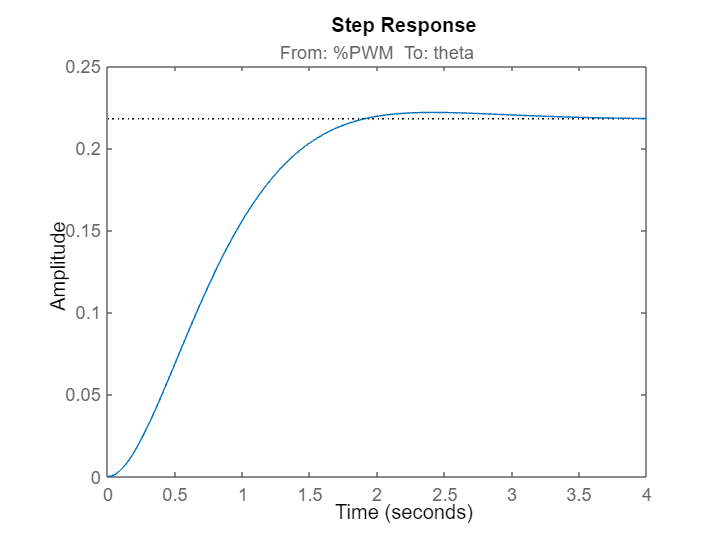

clear; clc; close all; 
addpath("../../../data/")
addpath("../../../controllers/Hinf/")
load("TF.mat")
ang_Lin = 85;
[Gss, G] = getNewTF(ang_Lin);
step(Gss); %% Lazo abierto de planta

Definición de las prestaciones: 

- Seguimiento de Referencia Perfecto (ep = 0) 

- Accion de Control entre (0 < u < 100) [ % PWM ]

- Menor tiempo posible (Mayor ancho de banda) 

- Rechazo a perturbaciones 

Definición de señales 

- ***El controlador recibe error en radianes y lo convierte a Porcentaje de PWM % ***

## Definición de Filtros de Ponderación

- $S$ -> Sensibilidad del sistema 

- KS -> Accion de control 

- T -> Sensibilidad Complementaria 


$$T+S=1$$
 

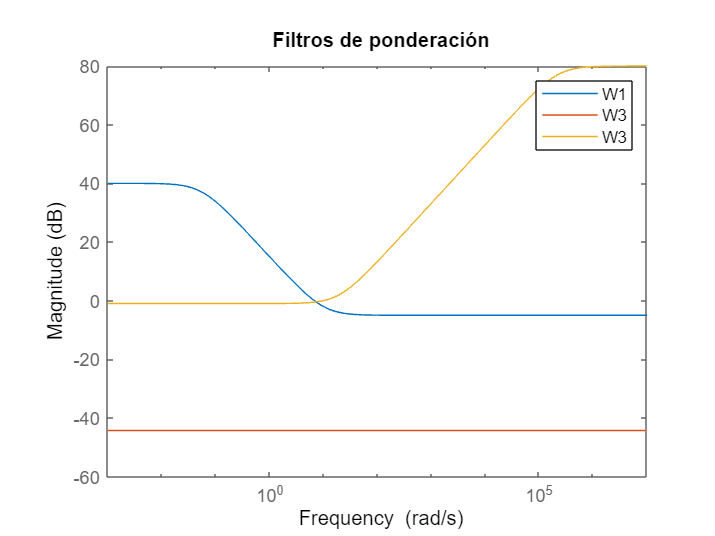

% Definición de filtros 

s = tf('s'); 
%W1 = makeweight(80, 0.4, 1e-6) * 1/(s/0.1 + 1);       %% Sensibilidad 
W2 = ss(1/100 * deg2rad(35));      %% Acción de Control  
%W3 = makeweight(1e-6,1.3, 200);      %% Sensibilidad Complementaria



freqC1=10;freqC2=32;freqC3=10;

% Selección de filtros 
W1 = makeweight(db2mag(40),[freqC1 db2mag(-2)],db2mag(-5)); % S 
%W2  =makeweight(db2mag(-35),[freqC2 db2mag(-32.5)],db2mag(-10)); % KS 
%W2 = db2mag(35*pi/180*30);
W3 = makeweight(db2mag(-1),[freqC3 db2mag(0)],db2mag(80)); % T


% Grafica de filtros 
bodemag(W1, W2, W3);
legend("W1", "W3", "W3"); 
title("Filtros de ponderación"); 


[K, CL, GAM] = mixsyn(Gss, W1, W2, W3); % Solucion problema H-infinito
GAM

GAM = 1.1742

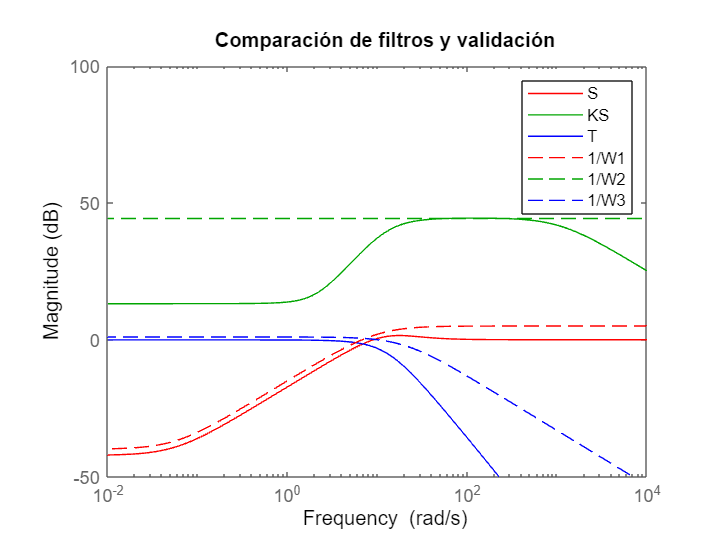


% Validación de filtros y H infinito 
S = feedback(1, K * G);
KS = K * S; 
T = 1 - S; 

% Graficas 
bodemag(S, "r-", KS, "g-", T, "b-"); hold on; 
bodemag(1/W1, "r--", 1/W2, "g--", 1/W3, 'b--'); hold off;
title("Comparación de filtros y validación"); 
legend("S", "KS", "T", "1/W1", "1/W2", "1/W3")
axis([1e-2 10e3, -50, 100]); 

## Respuesta de lazo cerrado

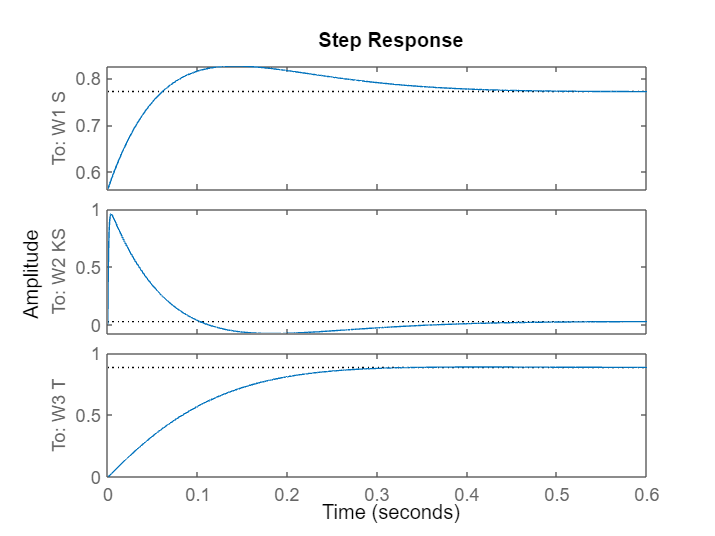

% MAtriz de transferencia aumentada
CL.OutputName = {'W1 S', 'W2 KS', 'W3 T'}; 
step(CL); 


OL = series(K, G); 
T = feedback(OL, 1); 
U = feedback(K, G); 


%% Respuesta directa 
step(T); 
BW = bandwidth(T)

BW = 9.8576

BW = BW/(2*pi)

BW = 1.5689

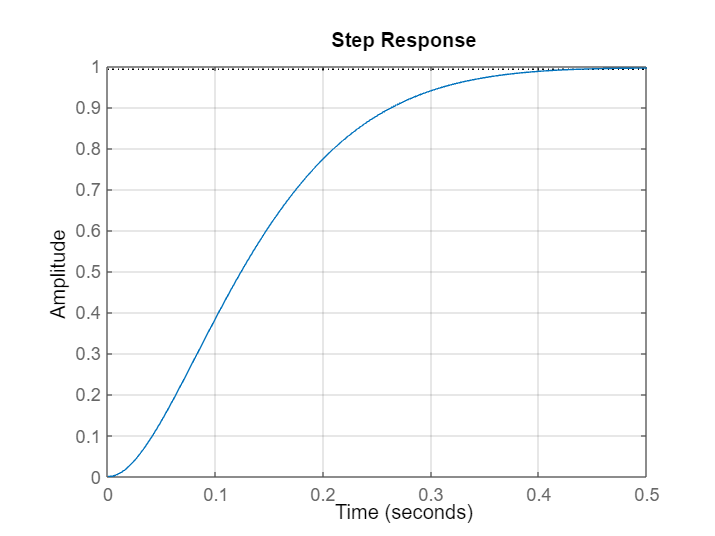

grid on; 

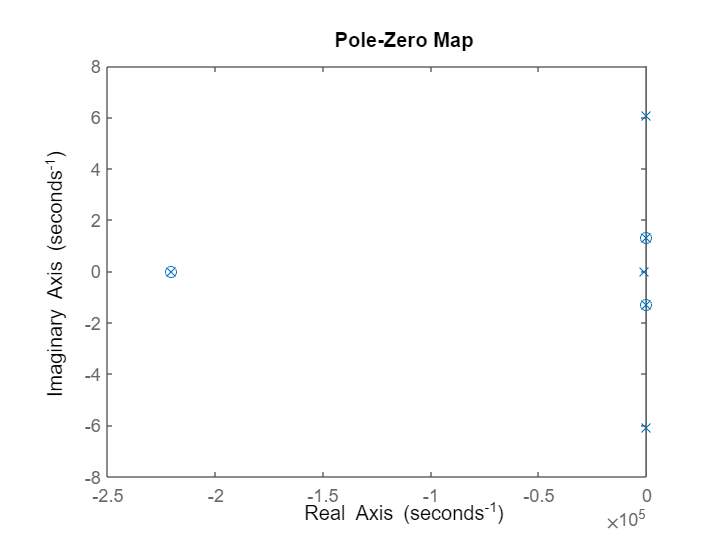


pzmap(T)

format long
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.67e+00 + 1.30e+00i     7.88e-01       2.11e+00         6.00e-01    
 -1.67e+00 - 1.30e+00i     7.88e-01       2.11e+00         6.00e-01    
 -1.14e+01 + 6.07e+00i     8.82e-01       1.29e+01         8.81e-02    
 -1.14e+01 - 6.07e+00i     8.82e-01       1.29e+01         8.81e-02    
 -1.08e+03                 1.00e+00       1.08e+03         9.23e-04    
 -2.21e+05                 1.00e+00       2.21e+05         4.54e-06    


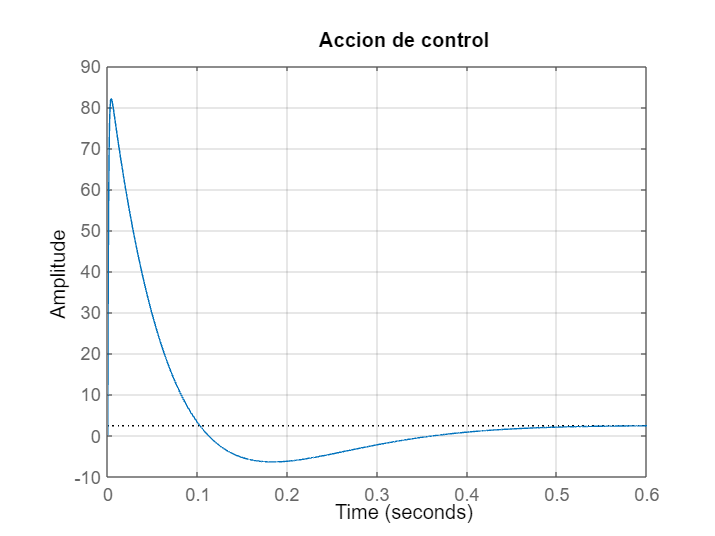


% Respuesta de accion de control
step(pi/6 * U);  
title("Accion de control"); grid on; 

% Función de transferencia; 
size(K); 

State-space model with 1 outputs, 1 inputs, and 4 states.


Ktf = tf(K); 

## Implementacion en arduino

Ts = 2.5e-3;  % Tiempo de muestreo

HinfDiscrete = c2d(K, Ts, 'tustin')

HinfDiscrete =
 
  A = 
              x1         x2         x3         x4
   x1     0.9999          0          0          0
   x2    0.03405    -0.9928     0.5828  0.0003058
   x3      0.115  4.088e-07     0.9681   0.001033
   x4      91.98   0.000327     -25.51     -0.174
 
  B = 
              u1
   x1      0.005
   x2  8.512e-05
   x3  0.0002874
   x4     0.2299
 
  C = 
               x1          x2          x3          x4
   y1   3.791e+04      0.1348  -1.051e+04      -480.4
 
  D = 
          u1
   y1  94.77
 
Sample time: 0.0025 seconds
Discrete-time state-space model.



%save("controllers/Hinf/Hinf.mat", "HinfDiscrete"); 
save("Hinf.mat", "HinfDiscrete"); 

## Revision en discreto

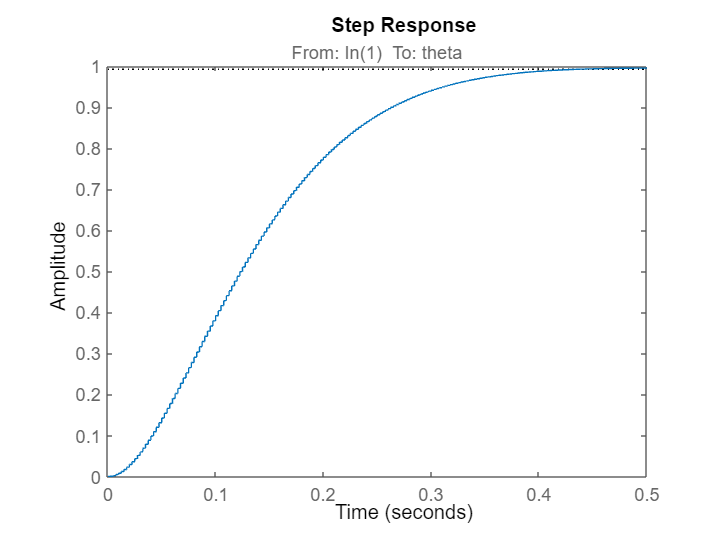

Gdiscrete = c2d(Gss, Ts, 'tustin'); 

Tdiscrete = feedback(series(HinfDiscrete, Gdiscrete), 1); 
step(Tdiscrete)

## Simulación Sistema No Lineal

DirectCMD = 30;
t1 = 60;
t2= 80;
v1 = 15;
v2 = -10;
v3 = -20;
%results = sim("controllers/Hinf/design/hinfNL.slx",100); 
results = sim("hinfNL.slx", timeR(end)); 

t = results.tout; % tiempo de simulación    

% Estados del sistema
theta = results.theta.Data;
ref = results.Ref.Data;
uSim = results.uSim.Data;

timeU = linspace(0,timeR(end),length(uSim))

timeU =                    0   0.002500000000000   0.005000000000000   0.007500000000000   0.010000000000000   0.012500000000000   0.015000000000000   0.017500000000000   0.020000000000000   0.022500000000000   0.025000000000000   0.027500000000000   0.030000000000000   0.032500000000000   0.035000000000000   0.037500000000000   0.040000000000000   0.042500000000000   0.045000000000000   0.047500000000000   0.050000000000000   0.052500000000000   0.055000000000000   0.057500000000000   0.060000000000000   0.062500000000000   0.065000000000000   0.067500000000000   0.070000000000000   0.072500000000000   0.075000000000000   0.077500000000000   0.080000000000000   0.082500000000000   0.085000000000000   0.087500000000000   0.090000000000000   0.092500000000000   0.095000000000000   0.097500000000000   0.100000000000000   0.102500000000000   0.105000000000000   0.107500000000000   0.110000000000000   0.112500000000000   0.115000000000000   0.117500000000000   0.120000000000000   0.1225000

CMD = lowpass(uR,100,1/2.5e-3)

CMD = 1.0e+02 *

   0.230889719951681
   0.325550342847815
   0.313948003997114
   0.284577933635871
   0.295673377780529
   0.310809512486049
   0.300519880665096
   0.292144234451271
   0.301383658903448
   0.305677296197945


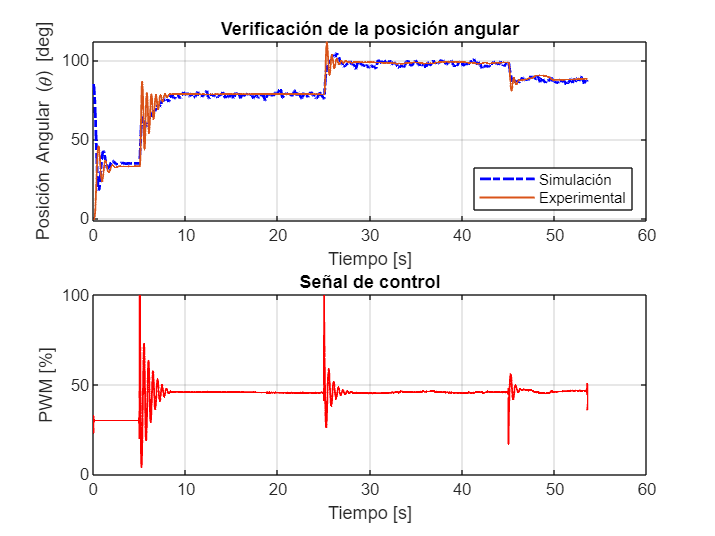


figure()
subplot(2,1,1)
plot(t,theta,"b-.","LineWidth",1.5);
hold on
plot(timeR,thetaRR,"LineWidth",1);
hold off
grid on
title('Verificación de la posición angular')
xlabel('Tiempo [s]')
ylabel('Posición Angular (\theta) [deg]')
legend('Simulación','Experimental','Location','southeast')
subplot(2,1,2)
plot(timeR,CMD,'r',"LineWidth",1);
grid on
ylim([0 100])
title('Señal de control')
xlabel('Tiempo [s]')
ylabel('PWM [%]')

%legend('Simulación','Experimental','Location','northeast')